# ergoCub Finger PID tuning

Copyright (C) 2023 Fondazione Istitito Italiano di Tecnologia (IIT)

All Rights Reserved.

% System identification and modelling 

### Read and plot datasets

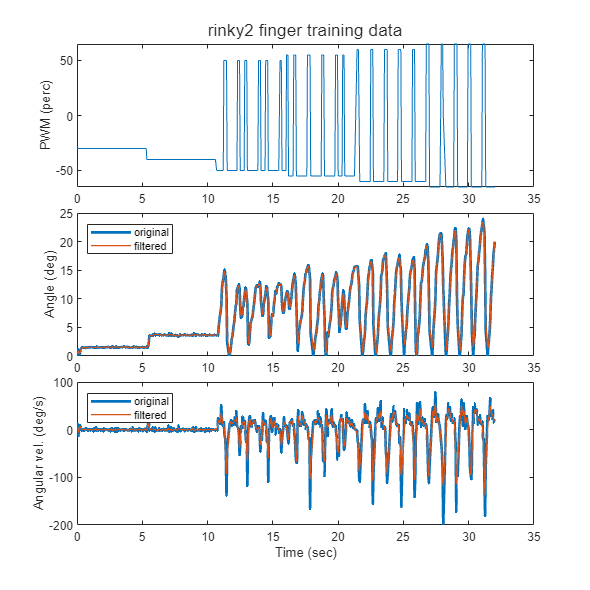

Ts = 0.05;
tau = 0.5;

% run init_ws to reset filename 
if( isempty(fname) ||  isempty(fpath))
    [fname, fpath] = uigetfile('*');
end
[pathstr, nameFile, ext] = fileparts(fname);
training_table = Reshape_dataset(fullfile(fpath,fname),  tau, 1, 0);
%Ts = mean(diff(training_table.Time)) % Ts is  now computed directly from data rather than imposed as a parameters

training_data = iddata(training_table.vel, training_table.pwm, Ts);
training_data.Name = "training";

f_train = figure('color', 'white','Position',[10 10 590 590]);
tiledlayout(3,1, "TileSpacing", "tight")

h1 = nexttile;
plot(training_table.Time, training_table.pwm);
ylabel("PWM (perc)")


h2 = nexttile;
plot(training_table.Time, training_table.pos_uf,'LineWidth',2);
hold on
plot(training_table.Time, training_table.pos,'LineWidth',1);
ylabel("Angle (deg)")
legend({"original", "filtered"},'Location','northwest')

h3 = nexttile;
plot(training_table.Time, training_table.vel_uf ,'LineWidth',2);
hold on
plot(training_table.Time, training_table.vel,'LineWidth',1);


legend({"original", "filtered"},'Location','northwest')
%legend({"filtered"})
ylabel("Angular vel. (deg/s)")
xlabel("Time (sec)")

linkaxes([h1 h2 h3], 'x')
sgtitle(strcat(nameFile, " finger training data"));

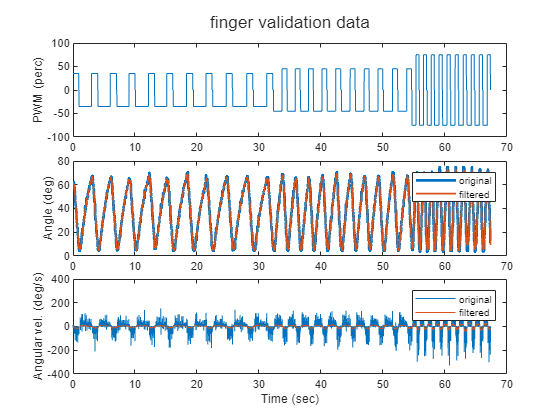

%Ts = 0.01;
tau = 5;

validation_table = prepare_dataset("data/validation.csv", Ts, tau);

validation_data = iddata(validation_table.vel, validation_table.pwm, Ts);
validation_data.Name = "validation";

figure('color', 'white');
tiledlayout(3,1, "TileSpacing", "tight")

h1 = nexttile;
plot(validation_table.Time, validation_table.pwm);
ylabel("PWM (perc)")


h2 = nexttile;
plot(validation_table.Time, validation_table.pos_uf,'LineWidth',2);
hold on
plot(validation_table.Time, validation_table.pos,'LineWidth',1.2);
ylabel("Angle (deg)")
legend({"original", "filtered"})


h3 = nexttile;
plot(validation_table.Time, validation_table.vel_uf);
hold on
plot(validation_table.Time, validation_table.vel);


legend({"original", "filtered"})
ylabel("Angular vel. (deg/s)")
xlabel("Time (sec)")

linkaxes([h1 h2 h3], 'x')
sgtitle("finger validation data")

### Run identification as process model

We target a continuous LTI model in the form


$$\frac{y}{u} = \frac{k (s - z_1)}{(s - p_1) ( s - p_2)}$$


The poles can be real or complex conjugate. 

opt = procestOptions;
opt.InitialCondition =  "zero";
model = procest(training_data, "P2ZU", opt);

s = tf('s');
finger_tf = tf(model);
zpk(finger_tf)

ans =
 
  From input "u1" to output "y1":
   -8.5371 (s+0.09388)
  ----------------------
  (s^2 + 10.59s + 31.68)
 
Continuous-time zero/pole/gain model.
Model Properties


Plot results.

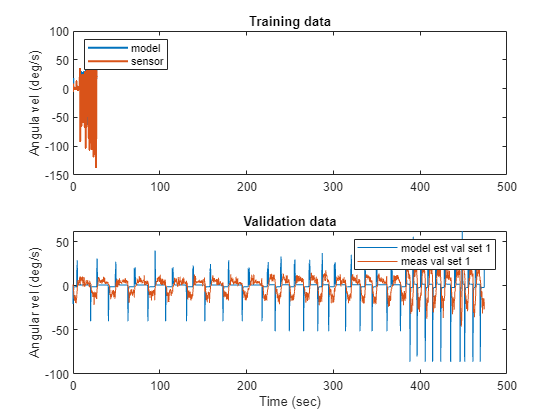

%[rmse, fig_handle] = plot_results(finger_tf, training_data, validation_data, Ts, Ts);
[rmse, fig_handle] = plot_results(finger_tf, training_data, validation_data, Ts, Ts);


disp(rmse)

     name: "Validation set 1 result"
    value: 15.3583




% Add uncertainty
% 
% Disabled because of complex values involved
% perc_uncertainty = 20;
% 
finger_zpk = zpk(finger_tf);
poles = finger_zpk.P{1};
zeros = finger_zpk.Z{1};
% 
% upoles(1) = ureal("p1", poles(1), "Percentage", [-perc_uncertainty, perc_uncertainty]);
% upoles(2) = ureal("p2", poles(2), "Percentage", [-perc_uncertainty, perc_uncertainty]);
% 
% uzero = ureal("z1", zeros, "Percentage", [-perc_uncertainty, perc_uncertainty]);
% 
% tfu = finger_zpk.K * (s - uzero) / ((s - upoles(1)) * (s - upoles(2)));
tfu = finger_zpk.K * (s - zeros) / ((s - poles(1)) * (s - poles(2)));

### Add integrator for position control

We change the IO relationship from  $\frac{\dot{\theta} }{u}$ to $\frac{\theta }{u}$  since we want to control the finger position.

tfu = tfu / s;

## Run autotuning

Here we define the specifications to tune the position controller in a robust way, and run the tuning algorithm.

#### Define tuning goals

Define the desired specifications.

select = menu('Choose Parameter Set', 'SN001', 'SN002', 'custom');

switch select

    case (1)
        parSet = '001';
        disp('option 1 - SN 001')
        Ts_controller = 1e-3;   % sec
        responsetime = 0.25;     % sec
        dcerror = 0.001;        % perc
        peakerror = 1.02;       % fract relative
        maxOvershoot = 2;       % perc
        phase_margin = 80;      % deg
        gain_margin = 3;        % dB
    case (2) % for now equal to SN 001
        disp('option 2 - SN 002')
        parSet = '002';
        Ts_controller = 1e-3;   % sec
        responsetime = 0.25;     % sec
        dcerror = 0.001;        % perc
        peakerror = 1.02;       % fract relative
        maxOvershoot = 2;       % perc
        phase_margin = 80;      % deg
        gain_margin = 3;        % dB
    case (3) %choose this one to play with parameters
        disp('option 3 - custom')
        parSet = 'cus';
        Ts_controller = Ts;   % sec
        responsetime = 0.5;     % sec
        dcerror = 0.005;        % perc
        peakerror = 1.1;       % fract relative
        maxOvershoot = 20;       % perc
        phase_margin = 80;      % deg
        gain_margin = 3;        % dB
end

option 3 - custom


par_summ = strcat('Ts: ', num2str(Ts), ', responsetime: ', num2str(responsetime), ', dcerror: ', num2str(dcerror), ...
    ', peakerror: ', num2str(peakerror), ', Overshoot: ', num2str(maxOvershoot) );
disp(par_summ);

Ts:0.05, responsetime:0.5, dcerror:0.005, peakerror:1.1, Overshoot:20


Define the goals.

tfu.InputName = "u";
tfu.OutputName = "y";

Rtrack = TuningGoal.Tracking('r', 'y', responsetime, dcerror, peakerror);
Rov = TuningGoal.Overshoot('r', 'y', maxOvershoot);
Rmargin = TuningGoal.Margins('y', gain_margin, phase_margin);

hard_goals = Rtrack;
soft_goals = [Rmargin, Rov];

disp('hard_goals: tracking ');

hard_goals: tracking 


disp('soft_goals: margin, overshoot');

soft_goals: margin, overshoot


#### Tune up the controller

Tune a PI controller. The D is zero since the system is highly damped due to friction.

[C, T] = design_robust_pid(tfu, soft_goals, hard_goals);

Plot tuning results.

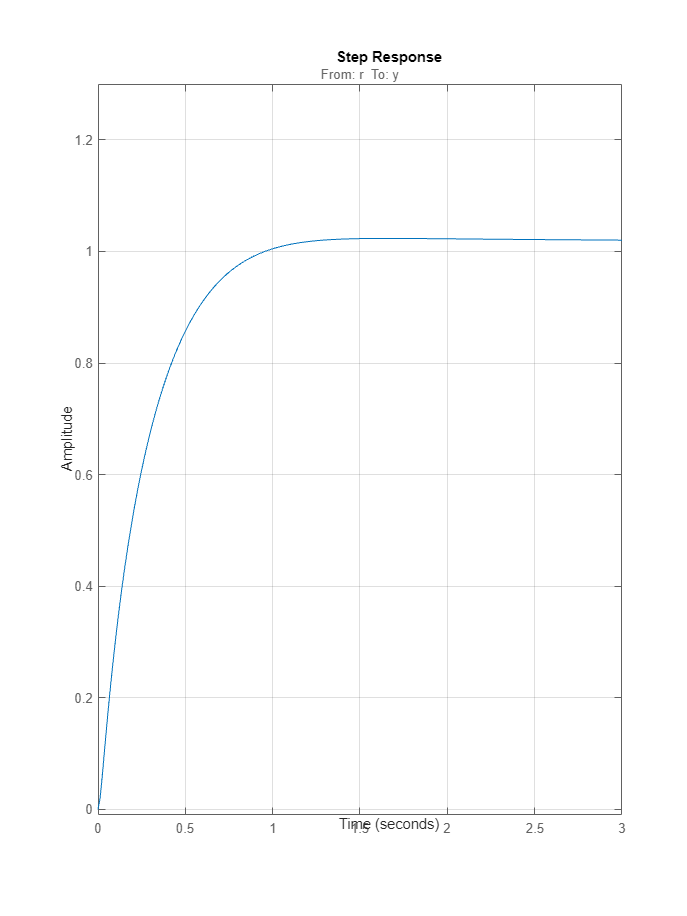

f_step = figure('color', 'white','Position',[10 10 900 1200]);
step(T, 3);
ylim([-0.01, 1.3])
grid('minor');


f_plots = figure('color', 'white');
viewGoal([hard_goals soft_goals], T)

Get the discretized controller.

Cz = c2d(C, Ts_controller, 'tustin')

Cz =
 
            Ts*(z+1)                 1         
  Kp + Ki * -------- + Kd * -------------------
            2*(z-1)         Tf+Ts/2*(z+1)/(z-1)

  with Kp = -4.38, Ki = -14, Kd = -0.428, Tf = 0.01, Ts = 0.05
 
Sample time: 0.05 seconds
Discrete-time PIDF controller in parallel form.
Model Properties


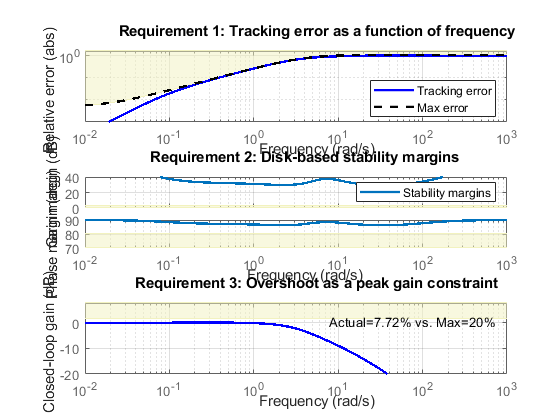


% saveas(f_train, f_name);
% exportgraphics(f_train, f_name);
% exportgraphics(f_resume, f_name,'append',true);
% exportgraphics(f_plots, f_name,'append',true);
kappapi = Cz.Kp;
kappai = Cz.Ki;
kappadi = Cz.Kd;
save(strcat('results/', nameFile,'-',parSet,'_',tYpe,'.mat'), 'nameFile','kappapi', 'kappai','kappadi')
% writematrix([nameFile , num2str(kappapi) , num2str(kappai) , num2str(kappadi)],strcat('results/', nameFile,'-',parSet,'_',tYpe,'.csv'))
waitforbuttonpress;

export('identification_tuning_v2.mlx',strcat('results/',nameFile,'-',parSet,'_',tYpe,'.pdf'), Format = "pdf", HideCode = true);